# Finding a 2D mixed-mode SSM for regular dynamics of an inverted flag from experiments

In this notebook we investigate a fluid - structure interaction problem. A flexible sheet, the flag, is placed in a water tunnel. The trailing edge (with respect to the flow direction) is clamped. 

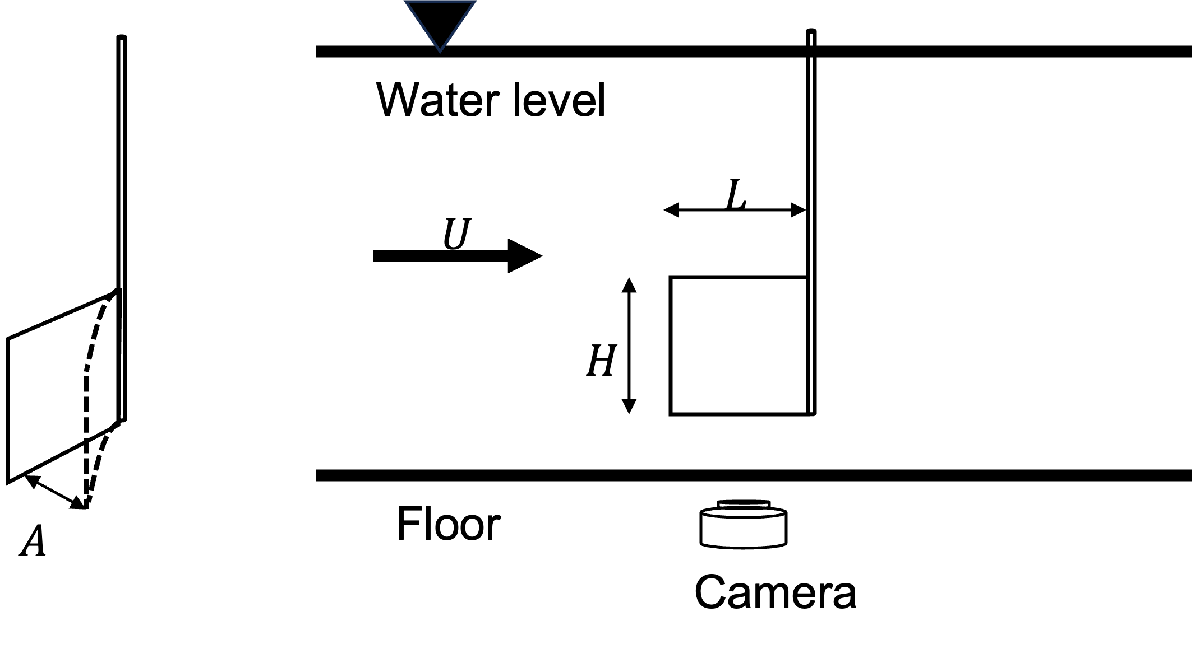

(Experiments taken in Coletti Lab: Institute of Fluid Dynamics, ETH Zurich)

The dynamics of an inverted flag exhibit different regimes as flow velocities increase in the water tunnel, leading to a decrease in the system's stiffness $K_B$. We briefly present the bifurcation diagram of an inverted flag and highlight the two states upon which our models are built: regular flapping and chaotic flapping.

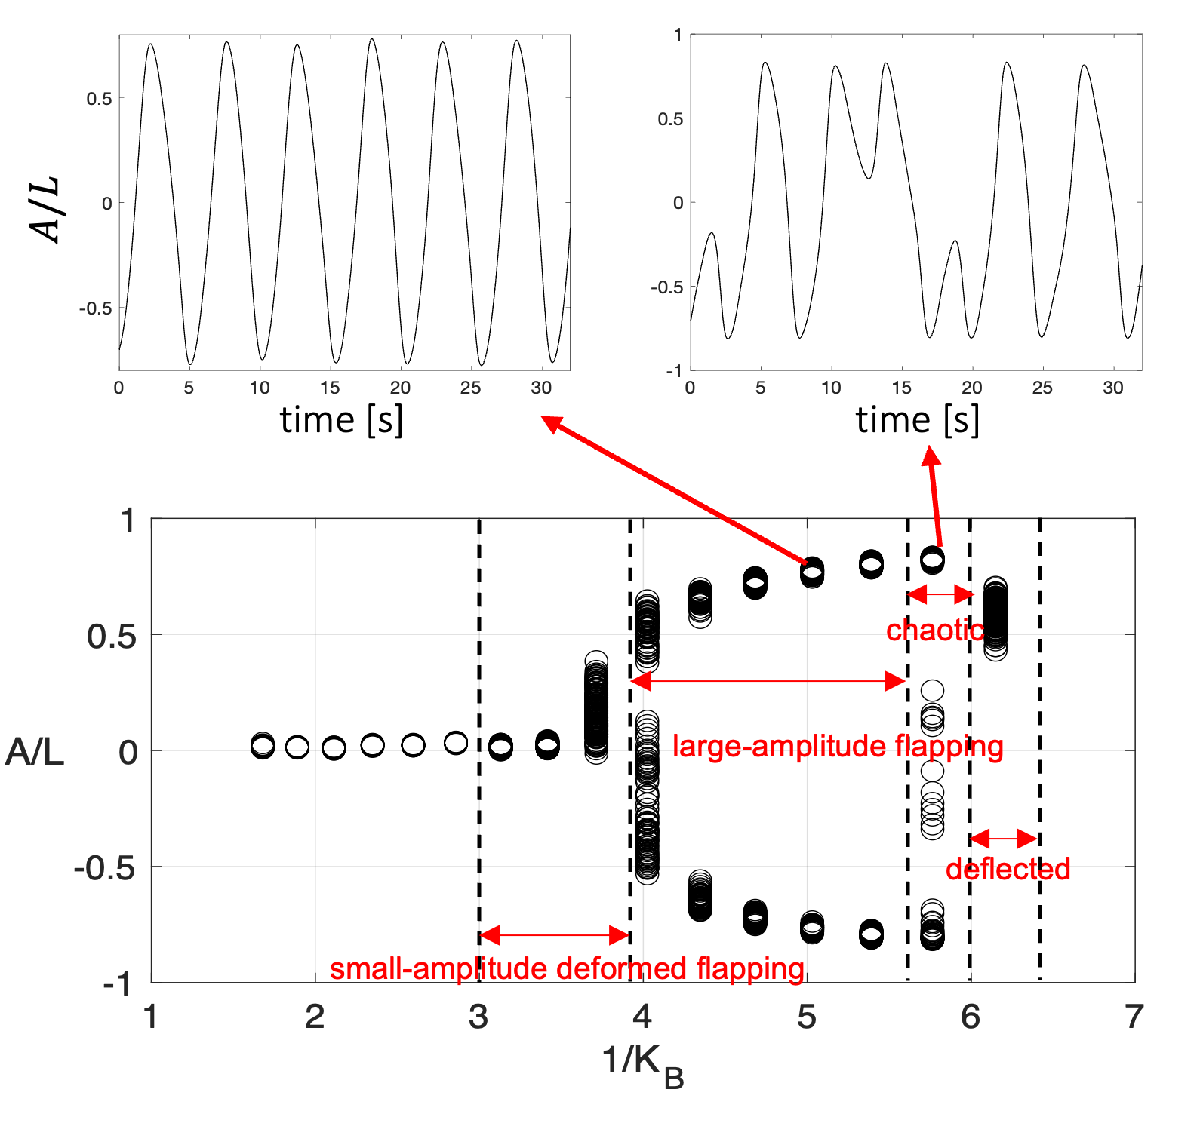

Video footage is recorded in the regime of large-amplitude flapping of the flag, which we call in short **flapping. **

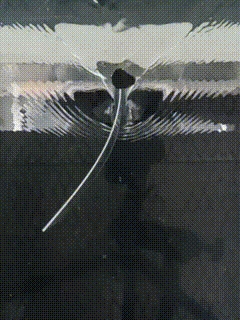

### References

[1] Z. Xu, B. Kaszás, M. Cenedese, G. Berti, F. Coletti, G. Haller, Data-driven modeling of the regular and chaotic dynamics of an inverted flag from experiments, [*J. Fluid Mech.*](https://www.cambridge.org/core/journals/journal-of-fluid-mechanics/article/datadriven-modelling-of-the-regular-and-chaotic-dynamics-of-an-inverted-flag-from-experiments/36D6DD09754069BF7EE05F9F3B50C988) (2024) 

[2] J. E. Sader, J. Cosse,  D. Kim, B. Fan, M. Gharib, Large-amplitude flapping of an inverted flag in a uniform steady flow–a vortex-induced vibration. [*J. Fluid Mech.*](https://www.cambridge.org/core/journals/journal-of-fluid-mechanics/article/abs/largeamplitude-flapping-of-an-inverted-flag-in-a-uniform-steady-flow-a-vortexinduced-vibration/388AEE925ABB33381CEE0157F32737DF) (2016)

## Loading the data for flapping dynamics

The experiment and the reduced-order modeling method is described in the paper [1].

The experiments for regular flapping dynamics were conducted with two sets of Reynolds numbers while keeping the stiffness $K_B$ to be the same: one at a low Reynolds number and the other at double that value. In both cases, experiments were conducted for $K_B =\frac{1}{4\ldotp 8}$  which leads to regular flapping. The Reynolds numbers are $\textrm{Re}=6\times {10}^4$ and  $\textrm{Re}={10}^5$ respectively.

### Loading Data for $\mathrm{Re}=6\times {10}^4$

The position of the flag tip was recorded using video footage and stored in 'xData.mat'. In total, 21 experiments were conducted at low Reynolds number case and 17 experiments at high Reynolds number case. In each set of experiments, 4 are used for testing.

We can plot the raw time series for a subset of the data. 

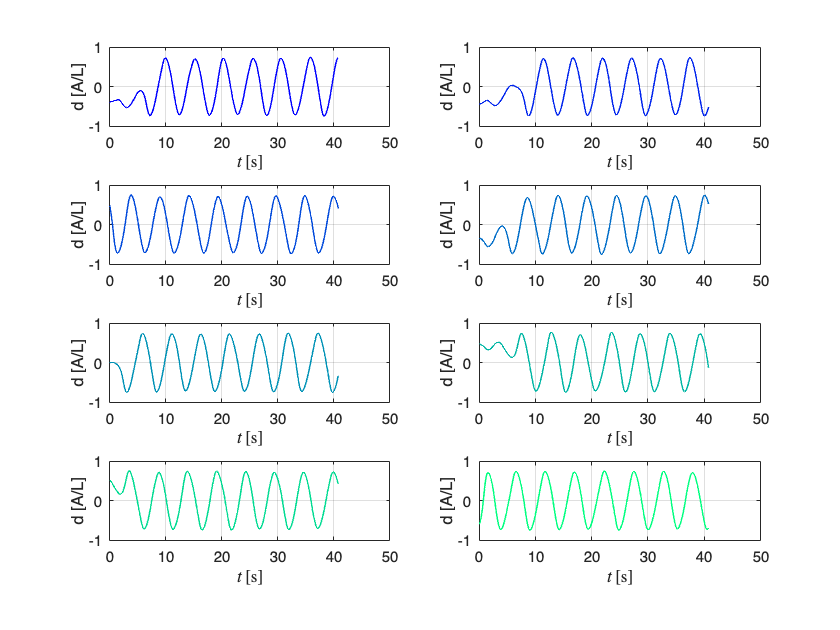

clearvars
close all
clc

load('xData.mat')

%% plot of trajectories in the experiments
nTraj = 8;
colors = winter(nTraj);
for i = 1:nTraj
    subplot(nTraj/2,2,i); hold on; grid on; box on;
    plot(xData{i,1},xData{i,2},'Linewidth',1,'Color',colors(i,:))
    xlabel('$t \, [$s$]$','Interpreter','latex')
    ylabel('d [A/L]')
end

indTrain = 1:17;
indTest = 18:21; 

## Loading Data at high $\textrm{Re}={10}^5$

We repeat the same analysis as in low Reynolds numbers. First we repeat the manifold fitting that we look for a 2-D manifold attached to the unstable middle fixed point, as it is still of saddle type.

We look for a polynomial parametrization of this SSM in the delay-embedded observable space as we have shown in the low Reynolds number case. We then plot the fitted manifold as well as trajectories.

load("HighReData.mat")
indTrain = 1:13;
indTest = 14:17;

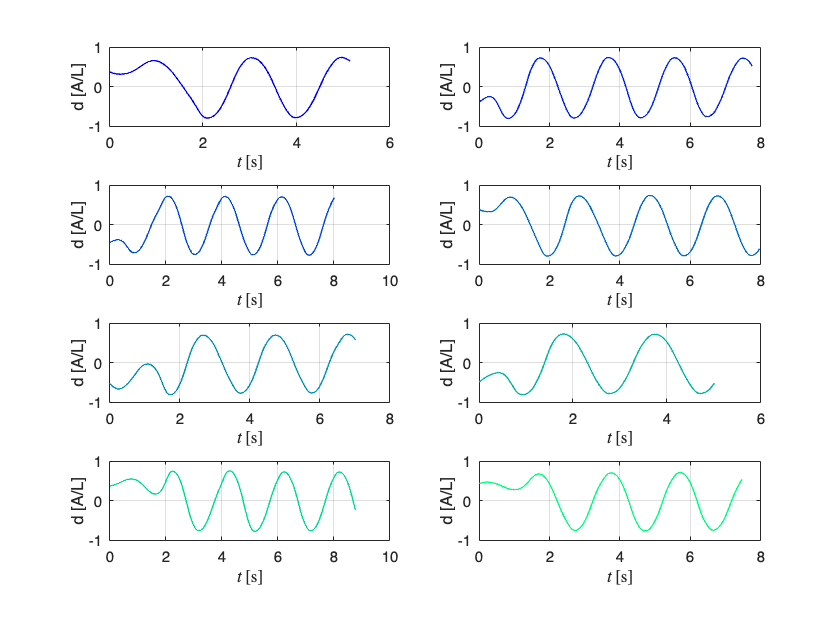

 %% plot of trajectories in the experiments
customFigure();
 nTraj = 8;
colors = winter(nTraj);
for i = 1:nTraj
    subplot(nTraj/2,2,i); hold on; grid on; box on;
    plot(xData_high{i,1},xData_high{i,2},'Linewidth',1,'Color',colors(i,:))
    xlabel('$t \, [$s$]$','Interpreter','latex')
    ylabel('d [A/L]')
end